# Jungle Bridge Rubber Bands

Ellie Kung & David Barsoum

data = load_excel_example

      RubberBandLabelOrColor                 Var2               Measurement_1    Measurement_2    Measurement_3    Measurement_4
    ___________________________    _________________________    _____________    _____________    _____________    _____________

    {'Rubber Band #1'         }    {'Mass (g)'             }          28               65              106              152     
    {'Blue thick band'        }    {'Stretched Length (cm)'}         7.5              7.8                8              8.4     
    {'Rubber Band #2'         }    {'Mass (g)'             }          43               76              106              152     
    {'Green tiny semi thick'  }    {'Stretched Length (cm)'}        2.25              2.4              2.5              2.7     
    {'Rubber Band #3'

data =    28.0000   65.0000  106.0000  152.0000
    7.5000    7.8000    8.0000    8.4000
   43.0000   76.0000  106.0000  152.0000
    2.2500    2.4000    2.5000    2.7000
   39.0000   69.0000  106.0000  152.0000
    9.3000    9.8000   10.8000   12.0000
   30.0000   75.0000  117.0000  152.0000
    3.5000    4.2000    5.5000    6.4000
   35.0000   77.0000  106.0000  152.0000
    8.1000    8.5000    8.8000    9.0000


### Exercise 22.1 - Construct A and Y Matrix ( First Band)

A = ones(4, 2);

A(:, 1) = data(2, :)'

A =     7.5000    1.0000
    7.8000    1.0000
    8.0000    1.0000
    8.4000    1.0000


Y = data(1, :)' * 9.8

Y = 1.0e+03 *

    0.2744
    0.6370
    1.0388
    1.4896



m_and_b = (A' * A) \ A'* Y

m_and_b = 1.0e+04 *

    0.1378
   -1.0063



k = m_and_b(1)

k = 1.3783e+03

l_0 =  -m_and_b(2) / k ;

### Line of Best Fit

x_val =0:100:1600;
y_val = (x_val - m_and_b(2))./m_and_b(1)

y_val =     7.3011    7.3736    7.4462    7.5187    7.5913    7.6638    7.7364    7.8090    7.8815    7.9541    8.0266    8.0992    8.1717    8.2443    8.3168    8.3894    8.4619


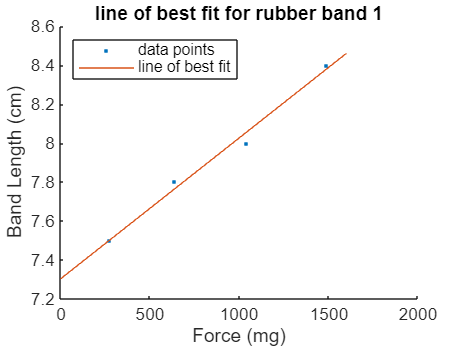


figure(); hold on;
plot(Y,A(:,1), '.')
plot(x_val, y_val)
xlabel('Force (mg)')
ylabel('Band Length (cm)')
title('line of best fit for rubber band 1')
legend('data points', 'line of best fit', Location='northwest')

### 3D Surface Plot

% % x = m, y = b
% m = m_and_b(1);
% b = m_and_b(2);
% 
% [M, B] = meshgrid(-10:0.5:10, -10:0.5:10);
% E = (M.*Y + B - A(:,1)).^2
% 
% surf(M, B, E);

### For Loop For All bands

k_list = zeros(1, 6);
l0_list = zeros(1,6);

j = 1;
for i = 1:2:12
    entry = data(i:i+1, :);

    A = ones(4, 2);
    A(:, 1) = entry(2, :)' .* .01;
    Y = entry(1, :)'./1000 .* 9.8;
    
    m_and_b = (A' * A) \ A'* Y;
    k = m_and_b(1);
    l_0 =  -m_and_b(2) / k;

    k_list(j) = k;
    l0_list(j) = l_0;
    j = j+1;
end

k_list

k_list =   137.8304  240.1287   39.9234   39.4518  121.0087  107.8447


l0_list

l0_list =     0.0730    0.0208    0.0823    0.0258    0.0785    0.0788
